clc;clear;
a=imread('pictures\rgb.jpg');
Q = 2;
REAL_SIM = false;

if REAL_SIM
    N = 16;
    K = 11;
    funENCO = @HammingENCO;
    funDECO = @HammingDECO;
    ADD_NOISE = false;
else
    N = 7;
    K = 4;
    funENCO = @HMENCO;
    funDECO = @HMDECO;
    ADD_NOISE = true;
end

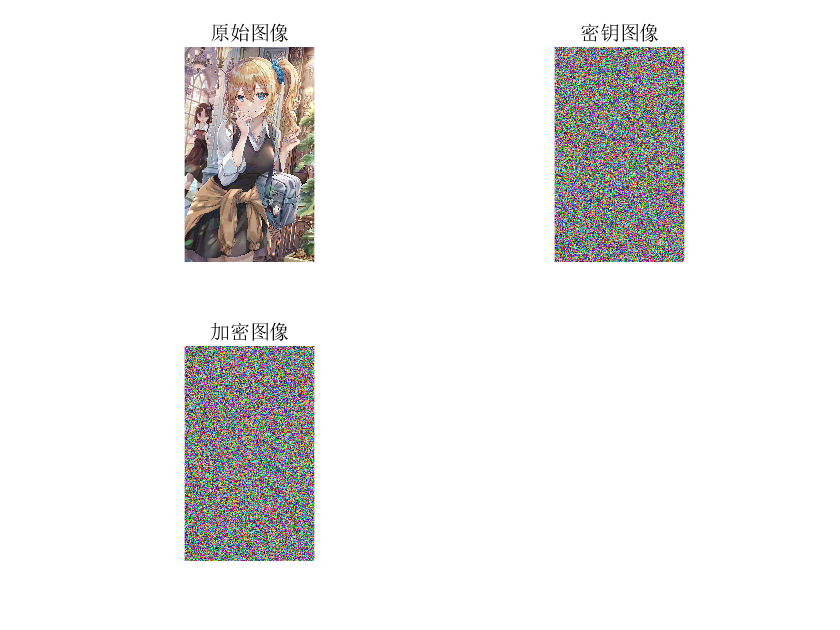

subplot(2,2,1);
imshow(a);
title('原始图像');
keys=rgb(0.32,size(a(:,:,1),1),size(a(:,:,1),2));
subplot(2,2,2);
imshow(keys);
title('密钥图像');
a_mi=bitxor(keys,a);
subplot(2,2,3);
imshow(a_mi);
title('加密图像');

[code1, code2, code3] = jpegENCO(a, Q);

r1 = HammingSeq(code1, N, K, funENCO);
r2 = HammingSeq(code2, N, K, funENCO);
r3 = HammingSeq(code3, N, K, funENCO);

p1 = BlockDiv(r1, length(r1) / N);
p2 = BlockDiv(r2, length(r2) / N);
p3 = BlockDiv(r3, length(r3) / N);

r1 = BlockDiv(p1, N);
r2 = BlockDiv(p2, N);
r3 = BlockDiv(p3, N);

code1 = InvHammingSeq(r1, N, K, funDECO);
code2 = InvHammingSeq(r2, N, K, funDECO);
code3 = InvHammingSeq(r3, N, K, funDECO);

out = uint8(jpegDECO(code1, code2, code3, Q));

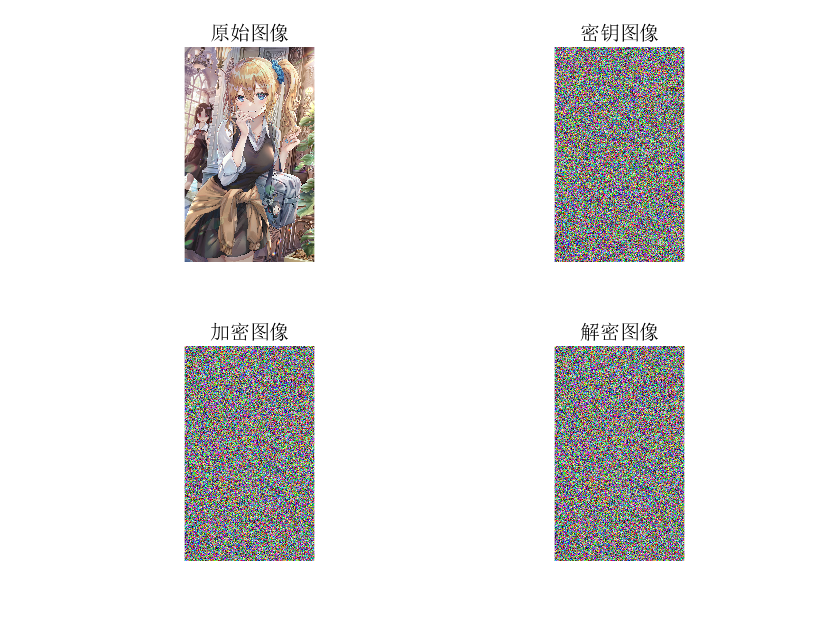

a_jie=bitxor(keys,out(1: size(a, 1), 1: size(a, 2), :));
subplot(2,2,4);
imshow(a_jie);
title('解密图像');